folderPath = 'D:\TechnicalReport\nTop Homogenisation';
files = dir(fullfile(folderPath, '*.csv'));
filenames = {files.name};

% Extract numeric values from filenames
numericValues = zeros(length(filenames), 1);
for i = 1:length(filenames)
    [~, name, ~] = fileparts(filenames{i});  % Remove .csv extension
    numericValues(i) = str2double(name);
end

% Sort filenames based on numeric values
[~, sortedIndices] = sort(numericValues);
sortedFilenames = filenames(sortedIndices);

% Import data from CSV files in sorted order
tables = cell(length(sortedFilenames), 1);
for i = 1:length(sortedFilenames)
    filePath = fullfile(folderPath, sortedFilenames{i});
    tables{i} = readtable(filePath);
    tables{i,2} = numericValues(sortedIndices(i));
    fprintf('Imported: %s\n', sortedFilenames{i});
end

Imported: 0.061629.csv
Imported: 0.077755.csv
Imported: 0.093613.csv
Imported: 0.10949.csv
Imported: 0.12496.csv
Imported: 0.13995.csv
Imported: 0.15539.csv
Imported: 0.17044.csv
Imported: 0.18505.csv
Imported: 0.19978.csv
Imported: 0.21471.csv
Imported: 0.22917.csv
Imported: 0.24343.csv
Imported: 0.25775.csv
Imported: 0.27242.csv
Imported: 0.28666.csv
Imported: 0.30039.csv
Imported: 0.31485.csv
Imported: 0.32872.csv
Imported: 0.34299.csv
Imported: 0.35659.csv
Imported: 0.37076.csv
Imported: 0.38495.csv
Imported: 0.39878.csv
Imported: 0.41238.csv
Imported: 0.42602.csv
Imported: 0.4403.csv
Imported: 0.45422.csv
Imported: 0.46783.csv
Imported: 0.48137.csv
Imported: 0.49533.csv
Imported: 0.50946.csv
Imported: 0.53673.csv
Imported: 0.55034.csv
Imported: 0.56438.csv
Imported: 0.57851.csv
Imported: 0.59217.csv
Imported: 0.60588.csv
Imported: 0.61962.csv
Imported: 0.63398.csv
Imported: 0.64808.csv
Imported: 0.66162.csv
Imported: 0.67599.csv
Imported: 0.70433.csv
Imported: 0.71814.csv
Imported

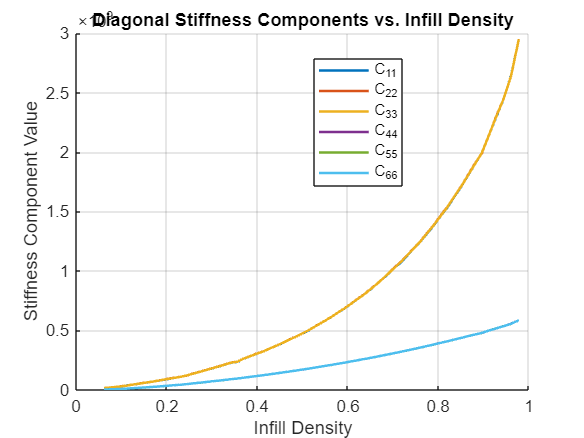

% Extract infill densities and stiffness matrices
num_files = length(tables);
densities = zeros(num_files, 1);
stiffness_data = zeros(num_files, 6, 6); % 3D array: [density, row, col]

for i = 1:num_files
    densities(i) = tables{i,2};        % Get density from second column
    current_table = tables{i,1};       % Get 6x6 table from first column
    stiffness_data(i, :, :) = current_table{:,:}; % Convert table to numeric array
end

figure;
hold on;
for diag_idx = 1:6
    plot(densities, squeeze(stiffness_data(:, diag_idx, diag_idx)), ...
        'LineWidth', 1.5, ...
        'DisplayName', sprintf('C_{%d%d}', diag_idx, diag_idx));
end
hold off;

xlabel('Infill Density');
ylabel('Stiffness Component Value');
title('Diagonal Stiffness Components vs. Infill Density');
legend('Location', 'best');
grid on;

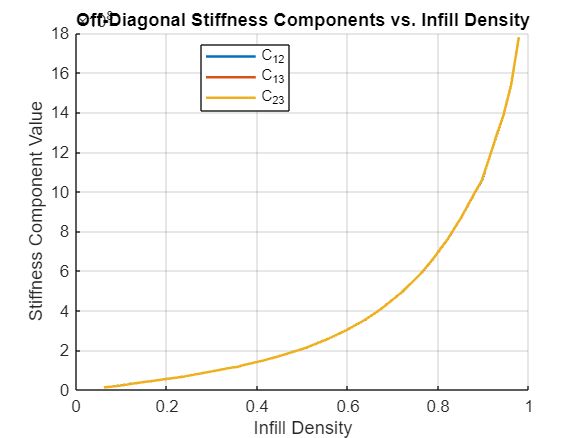


figure;
hold on;
plot(densities, squeeze(stiffness_data(:, 1, 2)), 'LineWidth', 1.5, 'DisplayName', 'C_{12}');
plot(densities, squeeze(stiffness_data(:, 1, 3)), 'LineWidth', 1.5, 'DisplayName', 'C_{13}');
plot(densities, squeeze(stiffness_data(:, 2, 3)), 'LineWidth', 1.5, 'DisplayName', 'C_{23}');
hold off;

xlabel('Infill Density');
ylabel('Stiffness Component Value');
title('Off-Diagonal Stiffness Components vs. Infill Density');
legend('Location', 'best');
grid on;

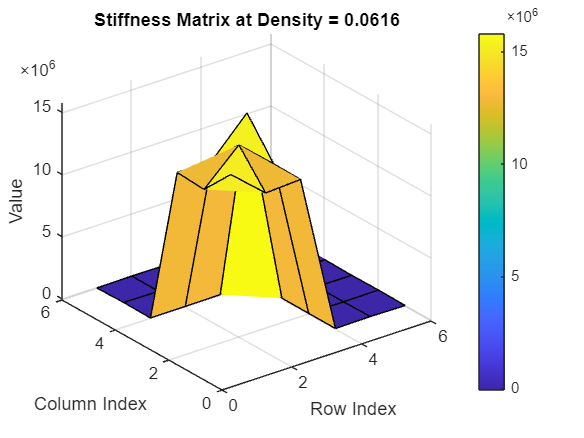

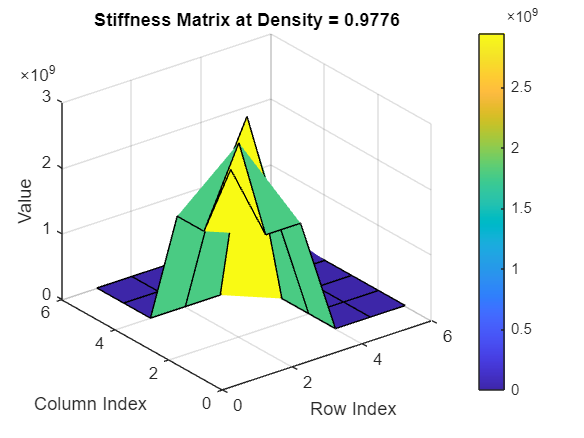


% Create meshgrid for matrix positions
[Row, Col] = meshgrid(1:6, 1:6);

figure;
for i = 1:num_files
    surf(Row, Col, squeeze(stiffness_data(i, :, :))');
    title(sprintf('Stiffness Matrix at Density = %.4f', densities(i)));
    xlabel('Row Index');
    ylabel('Column Index');
    zlabel('Value');
    colorbar;
    pause(0.1); % Adjust speed of animation
end

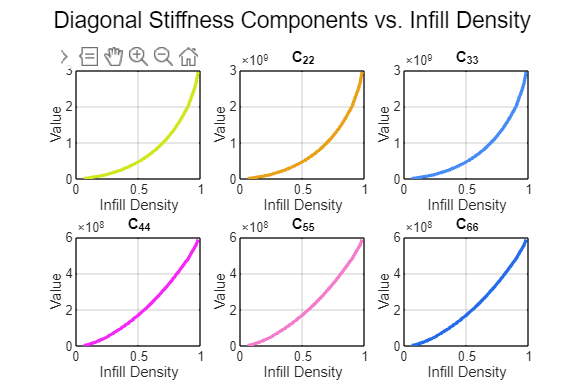

figure('Position', [100, 100, 1200, 800]); % Larger figure window

% Plot diagonal components C11, C22, ..., C66
component_labels = {'C_{11}', 'C_{22}', 'C_{33}', 'C_{44}', 'C_{55}', 'C_{66}'};
for diag_idx = 1:6
    subplot(2, 3, diag_idx);
    plot(densities, squeeze(stiffness_data(:, diag_idx, diag_idx)), ...
        'LineWidth', 2, 'Color', rand(1,3)); % Random colors for clarity
    xlabel('Infill Density');
    ylabel('Value');
    title(component_labels{diag_idx});
    grid on;
end
sgtitle('Diagonal Stiffness Components vs. Infill Density');

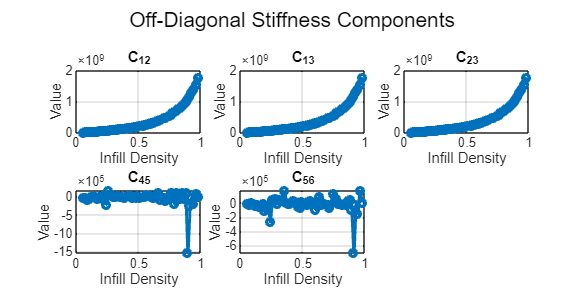



figure('Position', [100, 100, 1200, 600]);
off_diag_pairs = [1 2; 1 3; 2 3; 4 5; 5 6]; % Example critical off-diagonals
off_diag_labels = {'C_{12}', 'C_{13}', 'C_{23}', 'C_{45}', 'C_{56}'};

for i = 1:length(off_diag_pairs)
    subplot(2, 3, i);
    row = off_diag_pairs(i, 1);
    col = off_diag_pairs(i, 2);
    plot(densities, squeeze(stiffness_data(:, row, col)), ...
        'LineWidth', 2, 'Marker', 'o', 'MarkerSize', 4);
    xlabel('Infill Density');
    ylabel('Value');
    title(off_diag_labels{i});
    grid on;
end
sgtitle('Off-Diagonal Stiffness Components');